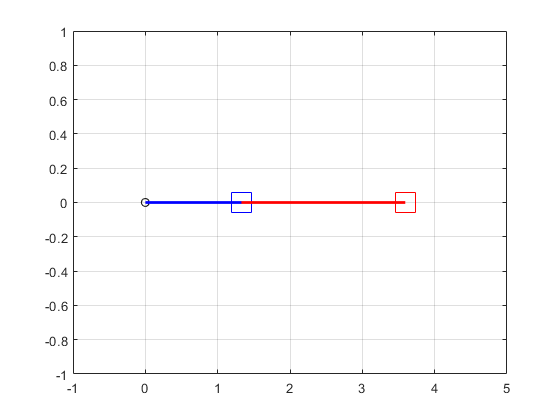

% dynamic simulation

clear all; clc; close all;

T=0.001;      % Sampling Period [sec]
Tfinal=60;     % 시뮬레이션 시간 [sec]
t=0:T:Tfinal; % 진행 시간 [sec]
N=length(t);  % 시뮬레이션 Sample 갯수 [Samples]

L1=0.41; L2=0.54; % Manipulator 링크 길이 [m]
m1=9; m2=1;       % Mass [kg]
k1 = 24; k2 = 3;
%% Generalized coordinate
% th: 각도[rad], dth:각속도[rad/s], ddth:각가속도[rad/s^2]
th=zeros(N,2); dth=zeros(N,2); ddth=zeros(N,2);
tau1=zeros(N,1); tau2=zeros(N,1); tau=zeros(N,2);
th(1,1)=0;  th(1,2)=0; %초기값 설정

for k=1:N
%     토크 입력(주어진 함수)
%     if k<2000,
        tau1(k)=cos(1.9*t(k));
        tau2(k)=0;
        tau(k,:)=[tau1(k) tau2(k)];
%     end
end

%% Simulation
for k=1:N-1
    
    %관성력항 계산
    M11(k)=m1;
    M12(k)=0;
    M21(k)=0;
    M22(k)=m2;
    M=[M11(k) M12(k); M21(k) M22(k)];
    M_inv =inv(M);
    
    
    K11(k)=k1+k2;
    K12(k)=-k2;
    K21(k)=-k2;
    K22(k)=k2;
    K=[K11(k) K12(k); K21(k) K22(k)];
    
    %forward dynamics (토크입력 -> 각가속도 출력)
    C_input=tau(k,:)'-K*th(k,:)'; %+(-2*sign(dth(k,:))-1*dth(k,:));
    ddth(k,:)=(M_inv*C_input);       %다음 샘플의 각가속도 계산
    dth(k+1,:)=dth(k,:)+ddth(k,:)*T;  %다음샘플의 각속도 계산
    th(k+1,:)=th(k,:)+dth(k+1,:)*T;   %다음샘플의 각도 계산
end

x=zeros(N,3); y=zeros(N,3); % 좌표계 위치 초기화
for k=1:N
    x(k,1)=0;
    y(k,1)=0;
    x(k,2)=th(k,1)+1.5;
    y(k,2)=0;
    x(k,3)=th(k,1)+th(k,2)+1.5+1.5;
    y(k,3)=0;
end

figure('color','w');
for k=1:200:N
    plot(x(k,1),y(k,1),'ko'); hold on; % Joint 1
    plot(x(k,2),y(k,2),'bs', 'MarkerSize', 20); hold on; % Joint 2
    plot(x(k,3),y(k,3),'rs', 'MarkerSize', 20); hold on; % Joint 3
    plot([x(k,1) x(k,2)],[y(k,1) y(k,2)],'b','linewidth',2); hold on; % Link 1
    plot([x(k,2) x(k,3)],[y(k,2) y(k,3)],'r','linewidth',2); hold on; % Link 2
    axis([-1 5 -1 1])                         % Axis X, Y
    grid on;
    drawnow;
    hold off;
end



figure('color','w');

subplot(211); % Graphs of end point
plot(t,tau1,'b','linewidth',2); hold on;
plot(t,tau2,'r','linewidth',2); hold on;
legend('τ_1','τ_2')
ylabel('Torque(Nm)'); xlabel('time(sec)')

subplot(212); % Graphs of joint angle
plot(t,th(:,1)*180/pi,'b','linewidth',2); hold on;
plot(t,th(:,2)*180/pi,'r','linewidth',2); hold on;
legend('θ_1','θ_2')
ylabel('Angle(deg)'); xlabel('time(sec)')


figure('color','w');

subplot(311); % Graphs of end point
plot(t,x(:,3),'b','linewidth',2); hold on;
ylabel('x3(m)'); xlabel('time(sec)')

subplot(312); % Graphs of joint angle
plot(t,y(:,3),'r','linewidth',2); hold on;
ylabel('y3(m)'); xlabel('time(sec)')

subplot(313); % Graphs of joint angle
plot(x(:,3),y(:,3),'b','linewidth',2); hold on;
ylabel('y3(m)'); xlabel('x3(m)')



